%singleChan
rasterSpikes = [AdjRasterSpikes180252; AdjRasterSpikes180253; AdjRasterSpikes180256; AdjRasterSpikes180257; AdjRasterSpikes180258; AdjRasterSpikes180260; AdjRasterSpikes196660; AdjRasterSpikes196661];
rasterSpikes = [rasterSpikes; NonClonSpikes5];

%16 channel
all16AdjSpikes  = [AdjRasterSpikes; rasterSpikes;NonClonSpikes15];

# 16 channel Raster with nonclons

result = all16AdjSpikes;
figure;
hold on;

% Define colors
orange = [1 0.5 0];
blue = [0 0 1];
red = [1 0 0]; % Define color for 'X'
darkGreen = [0 0.5 0]; % Define darker green color
darkRed = [0.5 0 0]; % Define darker red color

% Find unique units for each lightCycle
L_units = unique(result.unitID(result.lightCycle == 'L'));
D_units = unique(result.unitID(result.lightCycle == 'D'));
X_units = unique(result.unitID(result.lightCycle == 'X'));

% Combine the units with L first, then D, then X
combinedUnits = [L_units; D_units; X_units];
countUnits = length(combinedUnits) + 1;

% Loop through combined units and plot
for i = 1:length(combinedUnits)
    unitRows = result.unitID == combinedUnits(i);
    unitTimestamp = result.adjustedTimestamp(unitRows) / 60; % Convert to minutes
    lightCycle = result.lightCycle(find(unitRows, 1, 'first')); % Get the lightCycle value for this unit
    
    % Determine the color based on the lightCycle
    if lightCycle == 'L'
        color = orange;
    elseif lightCycle == 'D'
        color = blue;
    elseif lightCycle == 'X'
        color = red;
    end
    
    scatter(unitTimestamp, ones(size(unitTimestamp)) * i, 200, color, 'Marker', '|', 'SizeData', 20);
end

% Plot vertical lines after scatter plots to bring them to the front
line([15,15], [1,countUnits], 'Color', darkGreen, 'LineWidth', 1.5); % Use darker green
line([20,20], [1,countUnits], 'Color', 'r', 'LineWidth', 1.5);
line([45,45], [1,countUnits], 'Color', 'k', 'LineWidth', 1.5);

xMin = 0;
xMax = 50;

xlim([xMin, xMax]);

xlabel('Time(min)');
ylabel('Unit');
%title('Neuron Firing Across Time');

yticks(1:length(combinedUnits));
yticklabels(arrayfun(@num2str, combinedUnits, 'UniformOutput', false));
set(gca, 'YDir', 'reverse');

% Set the y-axis limit to match the actual number of units plotted
ylim([1, countUnits - 1]); % Adjust countUnits - 1 to avoid extra space

hold off;


Xample Raster

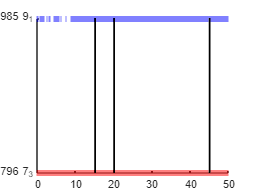

result = all16AdjSpikes;
figure;
hold on;

% Define colors
blue = [0 0 1]; % Color for 'D'
red = [1 0 0]; % Color for 'X'

% Find unique units for D and X lightCycles
D_units = unique(result.unitID(result.lightCycle == 'D'));
X_units = unique(result.unitID(result.lightCycle == 'X'));

% Randomly select 1 unit from each group (if fewer than 1, use all units)
rng('shuffle'); % Ensure randomness
D_units = D_units(randperm(length(D_units), min(1, length(D_units))));
X_units = X_units(randperm(length(X_units), min(1, length(X_units))));

% Combine the units, only D and X in this case
combinedUnits = [D_units; X_units];
countUnits = length(combinedUnits) + 1;

% Loop through combined units and plot
for i = 1:length(combinedUnits)
    unitRows = result.unitID == combinedUnits(i);
    unitTimestamp = result.adjustedTimestamp(unitRows) / 60; % Convert to minutes
    lightCycle = result.lightCycle(find(unitRows, 1, 'first')); % Get the lightCycle value for this unit
    
    % Determine the color based on the lightCycle
    if lightCycle == 'D'
        color = blue;
    elseif lightCycle == 'X'
        color = red;
    end
    
    scatter(unitTimestamp, ones(size(unitTimestamp)) * i, 1000, color, 'Marker', '|', 'SizeData', 20);
end

% Plot vertical lines after scatter plots to bring them to the front
line([15,15], [1,countUnits], 'Color', 'k', 'LineWidth', 1.5);
line([20,20], [1,countUnits], 'Color', 'k', 'LineWidth', 1.5);
line([45,45], [1,countUnits], 'Color', 'k', 'LineWidth', 1.5);

xMin = 0;
xMax = 50;

xlim([xMin, xMax]);

xlabel('Time(min)');
ylabel('Unit');
%title('Neuron Firing Across Time');

yticks(1:length(combinedUnits));
yticklabels(arrayfun(@num2str, combinedUnits, 'UniformOutput', false));
set(gca, 'YDir', 'reverse');

% Set the y-axis limit to match the actual number of units plotted
ylim([1, countUnits - 1]); % Adjust countUnits - 1 to avoid extra space

ax = gca; % Get current axes
ax.Position(2) = ax.Position(2) - 0.02; % Move the entire axes up

hold off;

## SingChan Raster

result = rasterSpikes;
figure;
hold on;

% Define colors
orange = [1 0.5 0];
blue = [0 0 1];
red = [1 0 0]; % Define color for 'X'
darkGreen = [0 0.5 0]; % Define darker green color
darkRed = [0.5 0 0]; % Define darker red color

% Find unique units for each lightCycle
L_units = unique(result.unitID(result.lightCycle == 'L'));
D_units = unique(result.unitID(result.lightCycle == 'D'));
X_units = unique(result.unitID(result.lightCycle == 'X'));

% Combine the units with L first, then D, then X
combinedUnits = [L_units; D_units; X_units];
countUnits = length(combinedUnits) + 1;

% Loop through combined units and plot
for i = 1:length(combinedUnits)
    unitRows = result.unitID == combinedUnits(i);
    unitTimestamp = result.adjustedTimestamp(unitRows) / 60; % Convert to minutes
    lightCycle = result.lightCycle(find(unitRows, 1, 'first')); % Get the lightCycle value for this unit
    
    % Determine the color based on the lightCycle
    if lightCycle == 'L'
        color = orange;
    elseif lightCycle == 'D'
        color = blue;
    elseif lightCycle == 'X'
        color = red;
    end
    
    scatter(unitTimestamp, ones(size(unitTimestamp)) * i, 200, color, 'Marker', '|', 'SizeData', 20);
end

% Plot vertical lines after scatter plots to bring them to the front
line([15,15], [1,countUnits], 'Color', 'K', 'LineWidth', 1.5); % Use darker green
line([20,20], [1,countUnits], 'Color', 'k', 'LineWidth', 1.5);
line([45,45], [1,countUnits], 'Color', 'k', 'LineWidth', 1.5);

xMin = 0;
xMax = 20;

xlim([xMin, xMax]);

xlabel('Time(min)');
ylabel('Unit');
%title('Neuron Firing Across Time');

yticks(1:length(combinedUnits));
yticklabels(arrayfun(@num2str, combinedUnits, 'UniformOutput', false));
set(gca, 'YDir', 'reverse');

% Set the y-axis limit to match the actual number of units plotted
ylim([1, countUnits - 1]); % Adjust countUnits - 1 to avoid extra space

hold off;

MultiChan Rasta

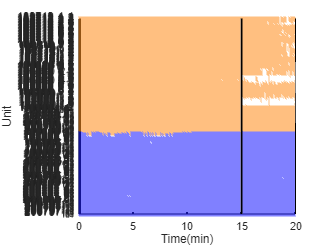

result = sixNASpikes;
figure;
hold on;

% Define colors
orange = [1 0.5 0];
blue = [0 0 1];
red = [1 0 0]; % Define color for 'X'
darkGreen = [0 0.5 0]; % Define darker green color
darkRed = [0.5 0 0]; % Define darker red color

% Find unique units for each lightCycle
L_units = unique(result.unitID(result.lightCycle == 'L'));
D_units = unique(result.unitID(result.lightCycle == 'D'));
X_units = unique(result.unitID(result.lightCycle == 'X'));

% Combine the units with L first, then D, then X
combinedUnits = [L_units; D_units; X_units];
countUnits = length(combinedUnits) + 1;

% Loop through combined units and plot
for i = 1:length(combinedUnits)
    unitRows = result.unitID == combinedUnits(i);
    unitTimestamp = result.adjustedTimestamp(unitRows) / 60; % Convert to minutes
    lightCycle = result.lightCycle(find(unitRows, 1, 'first')); % Get the lightCycle value for this unit
    
    % Determine the color based on the lightCycle
    if lightCycle == 'L'
        color = orange;
    elseif lightCycle == 'D'
        color = blue;
    elseif lightCycle == 'X'
        color = red;
    end
    
    scatter(unitTimestamp, ones(size(unitTimestamp)) * i, 200, color, 'Marker', '|', 'SizeData', 20);
end

% Plot vertical lines after scatter plots to bring them to the front
line([15,15], [1,countUnits], 'Color', 'K', 'LineWidth', 1.5); % Use darker green
line([20,20], [1,countUnits], 'Color', 'k', 'LineWidth', 1.5);
line([45,45], [1,countUnits], 'Color', 'k', 'LineWidth', 1.5);

xMin = 0;
xMax = 20;

xlim([xMin, xMax]);

xlabel('Time(min)');
ylabel('Unit');
%title('Neuron Firing Across Time');

yticks(1:length(combinedUnits));
yticklabels(arrayfun(@num2str, combinedUnits, 'UniformOutput', false));
set(gca, 'YDir', 'reverse');

% Set the y-axis limit to match the actual number of units plotted
ylim([1, countUnits - 1]); % Adjust countUnits - 1 to avoid extra space

hold off;

# FiringRate Box plot single Chan


% Combine the data for both BLFR and FSFR
combinedData = [singSpikeAves.BLFR; singSpikeAves.FSFR];

% Create a grouping variable for light cycle
combinedLightCycle = [singSpikeAves.lightCycle; singSpikeAves.lightCycle];

% Create a grouping variable for epoch
epoch = [repmat({'BLFR'}, length(singSpikeAves.BLFR), 1); repmat({'FSFR'}, length(singSpikeAves.FSFR), 1)];

% Convert to cell arrays of character vectors
combinedLightCycle = cellstr(combinedLightCycle);
epoch = cellstr(epoch);

% Combine light cycle and epoch into a single grouping variable
combinedCycleEpoch = strcat(combinedLightCycle, '_', epoch);



% Combine light cycle and epoch into a single grouping variable
combinedCycleEpoch = strcat(combinedLightCycle, '_', epoch);

% Reorder the combinedCycleEpoch to the desired order
uniqueGroups = {'Dark_BLFR', 'Light_BLFR', 'Dark_FSFR', 'Light_FSFR'};
[~, order] = ismember(combinedCycleEpoch, uniqueGroups);

% Sort combinedData and combinedCycleEpoch based on the desired order
[~, sortIdx] = sort(order);
combinedData = combinedData(sortIdx);
combinedCycleEpoch = combinedCycleEpoch(sortIdx);


% Plot the combined box plot
figure;
h = boxplot(combinedData, combinedCycleEpoch, 'Colors', [1 0.5 0; 0 0 1], 'Symbol', '');

% Increase the line width of the box plot
lineWidth = 4;
set(h, 'LineWidth', lineWidth);

% Customize the labels
ylabel('Firing Rate (Hz)', 'FontSize', 16, 'Color', 'k');
ylim([min(combinedData) max(combinedData)]);

% Customize the x-axis labels
xticks([1.5 3.5]);
xticklabels({'Baseline', 'Footshock'});
set(gca, 'FontSize', 16);

title('Single Channel');

% Add a legend for the colors
hold on;
h1 = plot(nan, nan, 'color', [0 0 1], 'LineWidth', 4); %  blue line for Dark
h2 = plot(nan, nan, 'color', [1 0.5 0], 'LineWidth', 4); % Orange line for Light
legend([h1, h2], {'Dark', 'Light'}, 'Location', 'northeast');
hold off;

% Set the text color to black and background color to white
set(gca, 'Color', 'w');
set(gca, 'XColor', 'k');
set(gca, 'YColor', 'k');
set(gcf, 'Color', 'w');


# ISI Box plot single Chan

 right

% Combine the data for both BLFR and FSFR
combinedData = [singSpikeAves.BLISI; singSpikeAves.FSISI];

% Create a grouping variable for light cycle
combinedLightCycle = [singSpikeAves.lightCycle; singSpikeAves.lightCycle];

% Create a grouping variable for epoch
epoch = [repmat({'BLISI'}, length(singSpikeAves.BLISI), 1); repmat({'FSISI'}, length(singSpikeAves.FSISI), 1)];

% Convert to cell arrays of character vectors
combinedLightCycle = cellstr(combinedLightCycle);
epoch = cellstr(epoch);

% Combine light cycle and epoch into a single grouping variable
combinedCycleEpoch = strcat(combinedLightCycle, '_', epoch);



% Combine light cycle and epoch into a single grouping variable
combinedCycleEpoch = strcat(combinedLightCycle, '_', epoch);

% Reorder the combinedCycleEpoch to the desired order
uniqueGroups = {'Dark_BLISI', 'Light_BLISI', 'Dark_ISI', 'Light_FSISI'};
[~, order] = ismember(combinedCycleEpoch, uniqueGroups);

% Sort combinedData and combinedCycleEpoch based on the desired order
[~, sortIdx] = sort(order);
combinedData = combinedData(sortIdx);
combinedCycleEpoch = combinedCycleEpoch(sortIdx);


% Plot the combined box plot
figure;
h = boxplot(combinedData, combinedCycleEpoch, 'Colors', [1 0.5 0; 0 0 1], 'Symbol', '');

% Increase the line width of the box plot
lineWidth = 4;
set(h, 'LineWidth', lineWidth);

% Customize the labels
ylabel('Interspike Interval (sec)', 'FontSize', 16, 'Color', 'k');
ylim([min(combinedData) max(4)]);

% Customize the x-axis labels
xticks([1.5 3.5]);
xticklabels({'Baseline', 'Footshock'});
set(gca, 'FontSize', 16);

title('Single Channel');

% Add a legend for the colors
hold on;
h1 = plot(nan, nan, 'color', [0 0 1], 'LineWidth', 4); % Dark blue line for Dark
h2 = plot(nan, nan, 'color', [1 0.5 0], 'LineWidth', 4); % Orange line for Light
legend([h1, h2], {'Dark', 'Light'}, 'Location', 'northeast');
hold off;

% Set the text color to black and background color to white
set(gca, 'Color', 'w');
set(gca, 'XColor', 'k');
set(gca, 'YColor', 'k');
set(gcf, 'Color', 'w');


# FiringRate Box plot 16 Chan

works

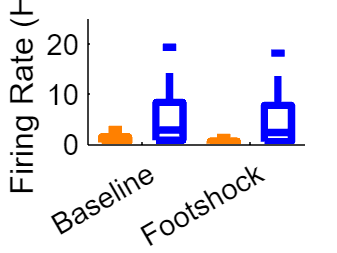

% Combine the data for both BLFR and FSFR
combinedData = [sixSpikeAves.BLFR; sixSpikeAves.FSFR];

% Create a grouping variable for light cycle
combinedLightCycle = [sixSpikeAves.lightCycle; sixSpikeAves.lightCycle];

% Create a grouping variable for epoch
epoch = [repmat({'BLFR'}, length(sixSpikeAves.BLFR), 1); repmat({'FSFR'}, length(sixSpikeAves.FSFR), 1)];

% Convert to cell arrays of character vectors
combinedLightCycle = cellstr(combinedLightCycle);
epoch = cellstr(epoch);

% Combine light cycle and epoch into a single grouping variable
combinedCycleEpoch = strcat(combinedLightCycle, '_', epoch);



% Combine light cycle and epoch into a single grouping variable
combinedCycleEpoch = strcat(combinedLightCycle, '_', epoch);

% Reorder the combinedCycleEpoch to the desired order
uniqueGroups = {'Dark_BLFR', 'Light_BLFR', 'Dark_FSFR', 'Light_FSFR'};
[~, order] = ismember(combinedCycleEpoch, uniqueGroups);

% Sort combinedData and combinedCycleEpoch based on the desired order
[~, sortIdx] = sort(order);
combinedData = combinedData(sortIdx);
combinedCycleEpoch = combinedCycleEpoch(sortIdx);

groupMeans = arrayfun(@(g) mean(combinedData(strcmp(combinedCycleEpoch, uniqueGroups{g}))), 1:numel(uniqueGroups));

% Plot the combined box plot
figure;
h = boxplot(combinedData, combinedCycleEpoch, 'Colors', [1 0.5 0; 0 0 1], 'Symbol', '');

% Increase the line width of the box plot
lineWidth = 4;
set(h, 'LineWidth', lineWidth);

% Customize the labels
ylabel('Firing Rate (Hz)', 'FontSize', 16, 'Color', 'k');
ylim([min(combinedData) max(25)]);

% Customize the x-axis labels
xticks([1.5 3.5]);
xticklabels({'Baseline', 'Footshock'});
set(gca, 'FontSize', 16);

%title('Multi Channel');

% Add a legend for the colors
hold on;
h1 = plot(nan, nan, 'color', [0 0 1], 'LineWidth', 4); % Dark blue line for Dark
h2 = plot(nan, nan, 'color', [1 0.5 0], 'LineWidth', 4); % Orange line for Light
%legend([h1, h2], {'Dark', 'Light'}, 'Location', 'northeast');
box off;
hold off;

set(gca, 'Color', 'w');
set(gca, 'XColor', 'k');
set(gca, 'YColor', 'k');

set(gcf, 'Color', 'w');


# ISI Box plot 16 Chan

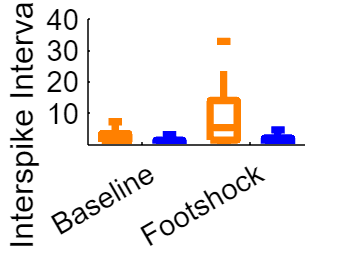

% Combine the data for both BLFR and FSFR
combinedData = [sixSpikeAves.BLISI; sixSpikeAves.FSISI];

% Create a grouping variable for light cycle
combinedLightCycle = [sixSpikeAves.lightCycle; sixSpikeAves.lightCycle];

% Create a grouping variable for epoch
epoch = [repmat({'BLISI'}, length(sixSpikeAves.BLISI), 1); repmat({'FSISI'}, length(sixSpikeAves.FSISI), 1)];

% Convert to cell arrays of character vectors
combinedLightCycle = cellstr(combinedLightCycle);
epoch = cellstr(epoch);

% Combine light cycle and epoch into a single grouping variable
combinedCycleEpoch = strcat(combinedLightCycle, '_', epoch);



% Combine light cycle and epoch into a single grouping variable
combinedCycleEpoch = strcat(combinedLightCycle, '_', epoch);

% Reorder the combinedCycleEpoch to the desired order
uniqueGroups = {'Dark_BLISI', 'Light_BLISI', 'Dark_ISI', 'Light_FSISI'};
[~, order] = ismember(combinedCycleEpoch, uniqueGroups);

% Sort combinedData and combinedCycleEpoch based on the desired order
[~, sortIdx] = sort(order);
combinedData = combinedData(sortIdx);
combinedCycleEpoch = combinedCycleEpoch(sortIdx);


% Plot the combined box plot
figure;
h = boxplot(combinedData, combinedCycleEpoch, 'Colors', [1 0.5 0; 0 0 1], 'Symbol', '');

% Increase the line width of the box plot
lineWidth = 4;
set(h, 'LineWidth', lineWidth);

% Customize the labels
ylabel('Interspike Interval (sec)', 'FontSize', 16, 'Color', 'k');
ylim([min(combinedData) max(40)]);



% Customize the x-axis labels
xticks([1.5 3.5]);
xticklabels({'Baseline', 'Footshock'});
set(gca, 'FontSize', 16);

% Add a legend for the colors
hold on;
h1 = plot(nan, nan, 'color', [0 0 1], 'LineWidth', 4); % Dark blue line for Dark
h2 = plot(nan, nan, 'color', [1 0.5 0], 'LineWidth', 4); % Orange line for Light
%legend([h1, h2], {'Dark', 'Light'}, 'Location', 'northeast');
box off;
hold off;

set(gca, 'Color', 'w');
set(gca, 'XColor', 'k');
set(gca, 'YColor', 'k');

set(gcf, 'Color', 'w');



Calculating averages in box plots

averageBLFR = varfun(@mean, sixSpikeAves, 'InputVariables', 'BLFR', ...
                     'GroupingVariables', 'lightCycle');
averageFSFR = varfun(@mean, sixSpikeAves, 'InputVariables', 'FSFR', ...
                     'GroupingVariables', 'lightCycle');

averageBLISI = varfun(@mean, sixSpikeAves, 'InputVariables', 'BLISI', ...
                     'GroupingVariables', 'lightCycle');
% Remove rows with NaN in FSISI
cleanedData = rmmissing(sixSpikeAves, 'DataVariables', 'FSISI');

% Calculate the average FSISI for each lightCycle group
averageFSISI = varfun(@mean, cleanedData, 'InputVariables', 'FSISI', ...
                      'GroupingVariables', 'lightCycle');

 Epoch by unit

Aves=singSpikeAves
% Color mapping for lightCycle (L = orange, D = blue)
colors = containers.Map({'L', 'D'}, {[1, 0.5, 0], [0, 0, 1]}); % Orange and Blue

% Create a figure and hold it for multiple plots
figure;
hold on;

% Loop through each row of the table
for i = 1:height(Aves)
    % Extract the BLFR, FSFR, and lightCycle for each unit
    blfr = Aves.BLFR(i);
    fsfr = Aves.FSFR(i);
    lightCycle = Aves.lightCycle(i); % Use parentheses for indexing


    % Set color based on the lightCycle
    color = colors(lightCycle);

    % Plot the BLFR an FSFR with connecting lines
    plot([0, 0.5], [blfr, fsfr], '-o', 'Color', color, 'MarkerFaceColor', color);
end

% Set axis labels and title
xticks([0, 0.5]);
xticklabels({'Baseline', 'FootShock'});
xlabel('Epoch');
ylabel('Firing Rate (Hz)');
%title('Firing Rate (BLFR and FSFR) for Each Unit by LightCycle');

% Show plot
hold off;


Epoch by unit with SEM

data = singAves;  % Assuming you have a table `data` with columns: 'BLFR', 'FSFR', 'ClonFR', 'lightCycle'

% Initialize an empty cell array for FR_change_status
data.FR_change_status = cell(height(data), 1);  % Ensure FR_change_status is a cell array

% Loop through the data and assign 'Increase' or 'Decrease' based on BLFR and FSFR
for i = 1:height(data)
    if data.FSFR(i) > data.BLFR(i)
        data.FR_change_status{i} = 'Increase';  % Store as string in the cell
    else
        data.FR_change_status{i} = 'Decrease';  % Store as string in the cell
    end
end

% Convert FR_change_status to categorical
data.FR_change_status = categorical(data.FR_change_status);

% Group data by lightCycle and FR_change_status
groups = findgroups(data.lightCycle, data.FR_change_status);
uniqueGroups = unique(groups);  % Define uniqueGroups here

% Define colors for each group
colors = containers.Map({'L Increase', 'L Decrease', 'D Increase', 'D Decrease'}, ...
                        {[1, 0.5, 0], [1, 1, 0], [0, 0, 1], [0, 0, 0.55]});

% Initialize figure
figure;
hold on;

% Iterate through each group and plot the data
for i = 1:numel(uniqueGroups)
    % Get the indices for the current group
    groupIdx = groups == uniqueGroups(i);

    % Extract data for the current group
    bl_values = data.BLFR(groupIdx);
    fs_values = data.FSFR(groupIdx);
    clon_values = data.ClonFR(groupIdx);

    % Compute means and SEM
    avg_values = [mean(bl_values), mean(fs_values), mean(clon_values)];
    sem_values = [std(bl_values) / sqrt(numel(bl_values)), ...
                  std(fs_values) / sqrt(numel(fs_values)), ...
                  std(clon_values) / sqrt(numel(clon_values))];

    % Determine the thickness of the line based on group size
    lineThickness = numel(bl_values) / 20;

    % Map group to a color
    gName = [char(data.lightCycle(find(groupIdx, 1))), ' ', char(data.FR_change_status(find(groupIdx, 1)))];
    color = colors(gName);

    % Plot the mean line with proportional thickness
    plot(1:3, avg_values, 'LineWidth', lineThickness, 'Color', color);

    % Plot the shaded area (SEM)
    fill([1, 2, 3, 3, 2, 1], ...
         [avg_values - sem_values, fliplr(avg_values + sem_values)], ...
         color, 'FaceAlpha', 0.2, 'EdgeColor', 'none');
  
    % Store legend entry
    legendEntries{i} = gName;
end

% Set x-ticks and labels
xticks(1:3);
xticklabels({'Baseline', 'FootShock', 'Clonidine'});

% Add labels and title
ylabel('Firing Rate(Hz)');
title('Single Channel');

% Plot the legend markers
hold on;
% Orange dot for 'Spontaneous (Light)'
h1 = plot(NaN, NaN, '-', 'Color', [1 0.5 0], 'MarkerFaceColor', [1 0.5 0], 'MarkerSize', 8);

% Blue dot for 'Spontaneous (Dark)'
h2 = plot(NaN, NaN, '-', 'Color', [0 0 1], 'MarkerFaceColor', [0 0 1], 'MarkerSize', 8);

% Black dot for 'Evoked'
h3 = plot(NaN, NaN, '-', 'Color', [1, 1, 0], 'MarkerFaceColor', [0 0 0], 'MarkerSize', 8);
h4 = plot(NaN, NaN, '-', 'Color', [0, 0, 0.55], 'MarkerFaceColor', [0 0 0], 'MarkerSize', 8);

% Create the legend (in the correct order)
legend([h1, h2, h3, h4], {'Light Increase', 'Dark Increase', 'Light Decrease', 'Dark Decrease'}, 'Location', 'northwest');

hold off;


# Paired points for response groups

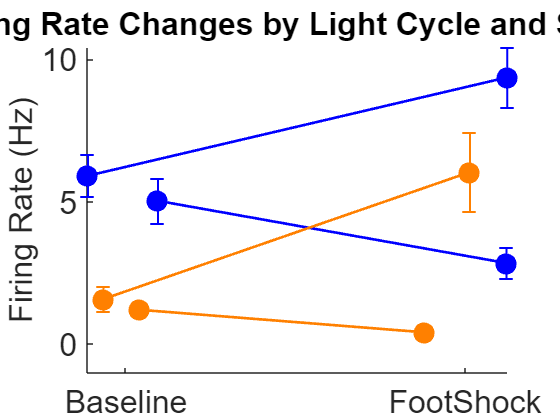

data = sixAves; % Assuming you have a table `data` with columns: 'BLFR', 'FSFR', 'lightCycle'

% Initialize an empty cell array for FR_change_status
data.FR_change_status = cell(height(data), 1); % Ensure FR_change_status is a cell array

% Loop through the data and assign 'Increase' or 'Decrease' based on BLFR and FSFR
for i = 1:height(data)
if data.FSFR(i) > data.BLFR(i)
data.FR_change_status{i} = 'Increase'; % Store as string in the cell
else
data.FR_change_status{i} = 'Decrease'; % Store as string in the cell
end
end

% Convert FR_change_status to categorical
data.FR_change_status = categorical(data.FR_change_status);

% Group data by lightCycle and FR_change_status
groups = findgroups(data.lightCycle, data.FR_change_status);

% Define colors for each group
colors = containers.Map({'L Increase', 'L Decrease', 'D Increase', 'D Decrease'}, ...
{[1, 0.5, 0], [1, 0.5, 0], [0, 0, 1], [0, 0, 1]});

% Initialize figure
figure;
hold on;

% Initialize variables for averages
averageFiringRates = struct();

% Set jitter parameters
jitterAmount = 0.3; % Amount of horizontal jitter for both baseline and footshock

% Iterate through each group and plot the data
for i = 1:max(groups)
    % Get the indices for the current group
    groupIdx = groups == i;

    % Extract data for the current group
    bl_values = data.BLFR(groupIdx);
    fs_values = data.FSFR(groupIdx);

    % Compute means
    avg_values = [mean(bl_values), mean(fs_values)];
    sem_values = [std(bl_values) / sqrt(length(bl_values)), std(fs_values) / sqrt(length(fs_values))];
    % Store averages for reporting
    groupName = [char(data.lightCycle(find(groupIdx, 1))), '_', char(data.FR_change_status(find(groupIdx, 1)))];
    averageFiringRates.(groupName) = struct('Baseline', avg_values(1), 'FootShock', avg_values(2));

    % Map group to a color
    color = colors(strrep(groupName, '_', ' ')); % Replace underscore back to space for the color map

    % Apply jitter for both baseline and footshock points
    baselineX = 1 + (rand - 0.5) * jitterAmount; % Add jitter around x = 1
    footshockX = 2 + (rand - 0.5) * jitterAmount; % Add jitter around x = 2

    % Plot the line connecting the jittered points
    plot([baselineX, footshockX], avg_values, 'LineWidth', 2, 'Color', color);

    % Plot scatter points with jitter for both baseline and footshock
    scatter(baselineX, avg_values(1), 250, 'MarkerEdgeColor', 'none', 'MarkerFaceColor', color, 'LineWidth', 2); % Baseline
    scatter(footshockX, avg_values(2), 250, 'MarkerEdgeColor', 'none', 'MarkerFaceColor', color, 'LineWidth', 2); % FootShock

   % Add error bars for standard errors
lowerBoundBaseline = max(0, avg_values(1) - sem_values(1)); % Ensure non-negative lower bound for baseline
lowerBoundFootShock = max(0, avg_values(2) - sem_values(2)); % Ensure non-negative lower bound for footshock

% Error bars for baseline
errorbar(baselineX, avg_values(1), avg_values(1) - lowerBoundBaseline, sem_values(1), ...
         'LineStyle', 'none', 'Color', color, 'LineWidth', 1.5, 'CapSize', 10);

% Error bars for footshock
errorbar(footshockX, avg_values(2), avg_values(2) - lowerBoundFootShock, sem_values(2), ...
         'LineStyle', 'none', 'Color', color, 'LineWidth', 1.5, 'CapSize', 10);


end

% Set x-ticks and labels
xticks([1, 2]); % Keep standard x-ticks
xticklabels({'Baseline', 'FootShock'});

% Add labels and title
set(gca, 'FontSize', 24, 'FontName', 'Arial');
ylabel('Firing Rate (Hz)', 'FontSize', 24, 'FontName', 'Arial');
title('Firing Rate Changes by Light Cycle and Status', 'FontSize', 24, 'FontName', 'Arial');

ylim([-1, max(ylim)]); % Extend the y-axis to -1 but keep the upper limit automatic




hold off;


% Display the average firing rates in the MATLAB command window
disp('Average Firing Rates (Hz) for Each Subgroup:');

Average Firing Rates (Hz) for Each Subgroup:


fields = fieldnames(averageFiringRates); % Get subgroup names

for i = 1:numel(fields)
    subgroup = fields{i}; % Current subgroup name
    baseline = averageFiringRates.(subgroup).Baseline; % Baseline average
    footshock = averageFiringRates.(subgroup).FootShock; % Footshock average
    fprintf('%s:\n', subgroup);
    fprintf(' Baseline: %.2f Hz\n', baseline);
    fprintf(' FootShock: %.2f Hz\n', footshock);
end

D_Decrease:


 Baseline: 5.02 Hz


 FootShock: 2.83 Hz


D_Increase:


 Baseline: 5.91 Hz


 FootShock: 9.37 Hz


L_Decrease:


 Baseline: 1.19 Hz


 FootShock: 0.40 Hz


L_Increase:


 Baseline: 1.57 Hz


 FootShock: 6.04 Hz



% Display the SEM for each subgroup in the MATLAB command window
disp('Standard Error of the Mean (SEM) for Each Subgroup:');

Standard Error of the Mean (SEM) for Each Subgroup:


for i = 1:numel(fields)
    subgroup = fields{i}; % Current subgroup
    semBaseline = std(data.BLFR(groups == i)) / sqrt(sum(groups == i)); % SEM for Baseline
    semFootshock = std(data.FSFR(groups == i)) / sqrt(sum(groups == i)); % SEM for Footshock
    fprintf('%s:\n', subgroup);
    fprintf(' SEM Baseline: %.2f Hz\n', semBaseline);
    fprintf(' SEM FootShock: %.2f Hz\n', semFootshock);
end

D_Decrease:


 SEM Baseline: 0.80 Hz


 SEM FootShock: 0.56 Hz


D_Increase:


 SEM Baseline: 0.74 Hz


 SEM FootShock: 1.06 Hz


L_Decrease:


 SEM Baseline: 0.13 Hz


 SEM FootShock: 0.07 Hz


L_Increase:


 SEM Baseline: 0.45 Hz


 SEM FootShock: 1.38 Hz


#### Baseline ANOVA within light groups

% Convert to strings and clean up
data.lightCycle = string(data.lightCycle);
data.FR_change_status = string(data.FR_change_status);
data.lightCycle = strtrim(data.lightCycle);
data.FR_change_status = strtrim(data.FR_change_status);

% Rename short labels if needed
data.lightCycle(data.lightCycle == 'L') = "Light";
data.lightCycle(data.lightCycle == 'D') = "Dark";

% Check unique values
disp('Unique lightCycle values:');

Unique lightCycle values:


disp(unique(data.lightCycle));

    "Dark"
    "Light"




% Check counts
tabulate(data.lightCycle)

  Value    Count   Percent
  Light      189     58.70%
   Dark      133     41.30%



% Loop through Light and Dark
uniqueCycles = unique(data.lightCycle);

for c = 1:length(uniqueCycles)
    currentCycle = uniqueCycles(c);
    
    % Subset data
    cycleData = data(data.lightCycle == currentCycle, :);
    
    % Count Increase and Decrease
    incCount = sum(cycleData.FR_change_status == "Increase");
    decCount = sum(cycleData.FR_change_status == "Decrease");
    
    fprintf('\nLight Cycle: %s\n', currentCycle);
    fprintf('Increase units: %d\n', incCount);
    fprintf('Decrease units: %d\n', decCount);
    
    % Only run ANOVA if both groups have at least 2 points
    if incCount >= 2 && decCount >= 2
        blfr = cycleData.BLFR;
        group = cycleData.FR_change_status;
        [p, tbl, stats] = anova1(blfr, group, 'off');
        disp(tbl);
        fprintf('p-value: %.4f\n', p);
    else
        fprintf('Skipping ANOVA for %s: insufficient data.\n', currentCycle);
    end
end


Light Cycle: Dark


Increase units: 55


Decrease units: 78


    {'Source'}    {'SS'        }    {'df' }    {'MS'      }    {'F'       }    {'Prob>F'  }
    {'Groups'}    {[   25.2247]}    {[  1]}    {[ 25.2247]}    {[  0.6106]}    {[  0.4360]}
    {'Error' }    {[5.4118e+03]}    {[131]}    {[ 41.3111]}    {0×0 double}    {0×0 double}
    {'Total' }    {[5.4370e+03]}    {[132]}    {0×0 double}    {0×0 double}    {0×0 double}



p-value: 0.4360



Light Cycle: Light


Increase units: 24


Decrease units: 165


    {'Source'}    {'SS'      }    {'df' }    {'MS'      }    {'F'       }    {'Prob>F'  }
    {'Groups'}    {[  2.9731]}    {[  1]}    {[  2.9731]}    {[  0.9460]}    {[  0.3320]}
    {'Error' }    {[587.6813]}    {[187]}    {[  3.1427]}    {0×0 double}    {0×0 double}
    {'Total' }    {[590.6545]}    {[188]}    {0×0 double}    {0×0 double}    {0×0 double}



p-value: 0.3320


#### Foot shock ANOVA within groups

% --- Clean up lightCycle & FR_change_status columns ---
data.lightCycle = string(data.lightCycle);
data.FR_change_status = string(data.FR_change_status);

% Remove whitespace
data.lightCycle = strtrim(data.lightCycle);
data.FR_change_status = strtrim(data.FR_change_status);

% Optional: Replace short labels if needed
data.lightCycle(data.lightCycle == 'L') = "Light";
data.lightCycle(data.lightCycle == 'D') = "Dark";

% Display unique values and counts for sanity check
disp('Unique lightCycle values:');

Unique lightCycle values:


disp(unique(data.lightCycle));

    "Dark"
    "Light"



tabulate(data.lightCycle);

  Value    Count   Percent
  Light      189     58.70%
   Dark      133     41.30%



% --- Loop through Light and Dark cycles ---
uniqueCycles = unique(data.lightCycle);

for c = 1:length(uniqueCycles)
    currentCycle = uniqueCycles(c);
    
    % Subset data for current light cycle
    cycleData = data(data.lightCycle == currentCycle, :);
    
    % Count Increase and Decrease units
    incCount = sum(cycleData.FR_change_status == "Increase");
    decCount = sum(cycleData.FR_change_status == "Decrease");
    
    fprintf('\nLight Cycle: %s\n', currentCycle);
    fprintf('Increase units: %d\n', incCount);
    fprintf('Decrease units: %d\n', decCount);
    
    % --- Only run ANOVA if both groups have at least 2 points ---
    if incCount >= 2 && decCount >= 2
        fsfr = cycleData.FSFR; % <-- Using FSFR here!
        group = cycleData.FR_change_status;
        
        [p, tbl, stats] = anova1(fsfr, group, 'off'); % Suppress plot
        
        % Display ANOVA results
        fprintf('\nANOVA Comparing FSFR (FootShock Firing Rate) for %s Cycle:\n', currentCycle);
        disp(tbl);
        fprintf('p-value: %.4f\n', p);
    else
        fprintf('Skipping ANOVA for %s: insufficient data.\n', currentCycle);
    end
end


Light Cycle: Dark


Increase units: 55


Decrease units: 78



ANOVA Comparing FSFR (FootShock Firing Rate) for Dark Cycle:


    {'Source'}    {'SS'        }    {'df' }    {'MS'        }    {'F'       }    {'Prob>F'    }
    {'Groups'}    {[1.3779e+03]}    {[  1]}    {[1.3779e+03]}    {[ 34.4875]}    {[3.3384e-08]}
    {'Error' }    {[5.2339e+03]}    {[131]}    {[   39.9538]}    {0×0 double}    {0×0 double  }
    {'Total' }    {[6.6119e+03]}    {[132]}    {0×0 double  }    {0×0 double}    {0×0 double  }



p-value: 0.0000



Light Cycle: Light


Increase units: 24


Decrease units: 165



ANOVA Comparing FSFR (FootShock Firing Rate) for Light Cycle:


    {'Source'}    {'SS'        }    {'df' }    {'MS'      }    {'F'       }    {'Prob>F'    }
    {'Groups'}    {[  666.4670]}    {[  1]}    {[666.4670]}    {[104.5763]}    {[8.8500e-20]}
    {'Error' }    {[1.1918e+03]}    {[187]}    {[  6.3730]}    {0×0 double}    {0×0 double  }
    {'Total' }    {[1.8582e+03]}    {[188]}    {0×0 double}    {0×0 double}    {0×0 double  }



p-value: 0.0000


# 16 channel subpops line graphs

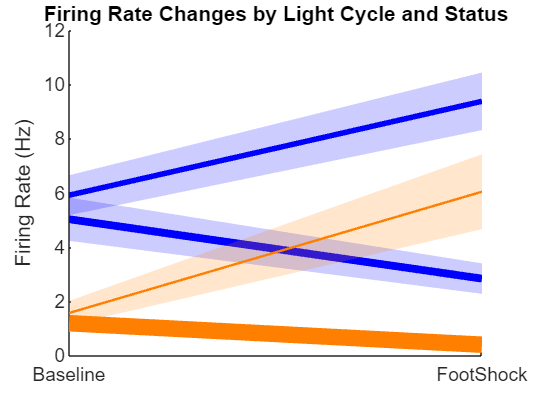

data = sixAves; % Assuming you have a table `data` with columns: 'BLFR', 'FSFR', 'lightCycle'

% Initialize an empty cell array for FR_change_status
data.FR_change_status = cell(height(data), 1); % Ensure FR_change_status is a cell array

% Loop through the data and assign 'Increase' or 'Decrease' based on BLFR and FSFR
for i = 1:height(data)
if data.FSFR(i) > data.BLFR(i)
data.FR_change_status{i} = 'Increase'; % Store as string in the cell
else
data.FR_change_status{i} = 'Decrease'; % Store as string in the cell
end
end

% Convert FR_change_status to categorical
data.FR_change_status = categorical(data.FR_change_status);

% Group data by lightCycle and FR_change_status
groups = findgroups(data.lightCycle, data.FR_change_status);

% Define colors for each group
colors = containers.Map({'L Increase', 'L Decrease', 'D Increase', 'D Decrease'}, ...
{[1, 0.5, 0], [1, 0.5, 0], [0, 0, 1], [0, 0, 1]});

% Initialize variables for averages
averageFiringRates = struct();

% Initialize figure
figure;
hold on;

% Iterate through each group and plot the data
for i = 1:max(groups)
% Get the indices for the current group
groupIdx = groups == i;

% Extract data for the current group
bl_values = data.BLFR(groupIdx);
fs_values = data.FSFR(groupIdx);

% Compute means and SEM
avg_values = [mean(bl_values), mean(fs_values)];
sem_values = [std(bl_values) / sqrt(numel(bl_values)), ...
std(fs_values) / sqrt(numel(fs_values))];

% Store averages for reporting
groupName = [char(data.lightCycle(find(groupIdx, 1))), '_', char(data.FR_change_status(find(groupIdx, 1)))];
averageFiringRates.(groupName) = struct('Baseline', avg_values(1), 'FootShock', avg_values(2));

% Determine the thickness of the line based on group size
lineThickness = numel(bl_values) / 20;

% Map group to a color
color = colors(strrep(groupName, '_', ' ')); % Replace underscore back to space for the color map

% Plot the mean line with proportional thickness
plot(1:2, avg_values, 'LineWidth', lineThickness, 'Color', color);

% Plot the shaded area (SEM)
fill([1, 2, 2, 1], ...
[avg_values - sem_values, fliplr(avg_values + sem_values)], ...
color, 'FaceAlpha', 0.2, 'EdgeColor', 'none');
end

% Set x-ticks and labels
xticks(1:2);
xticklabels({'Baseline', 'FootShock'});

% Add labels and title
ylabel('Firing Rate (Hz)');
title('Firing Rate Changes by Light Cycle and Status');

hold off;


% Display the average firing rates in the MATLAB command window
disp('Average Firing Rates (Hz) for Each Subgroup:');

Average Firing Rates (Hz) for Each Subgroup:


fields = fieldnames(averageFiringRates); % Get subgroup names

for i = 1:numel(fields)
subgroup = fields{i}; % Current subgroup name
baseline = averageFiringRates.(subgroup).Baseline; % Baseline average
footshock = averageFiringRates.(subgroup).FootShock; % Footshock average
fprintf('%s:\n', subgroup);
fprintf(' Baseline: %.2f Hz\n', baseline);
fprintf(' FootShock: %.2f Hz\n', footshock);
end

D_Decrease:


 Baseline: 5.02 Hz


 FootShock: 2.83 Hz


D_Increase:


 Baseline: 5.91 Hz


 FootShock: 9.37 Hz


L_Decrease:


 Baseline: 1.19 Hz


 FootShock: 0.40 Hz


L_Increase:


 Baseline: 1.57 Hz


 FootShock: 6.04 Hz


# Playing around with subplots all units jittered

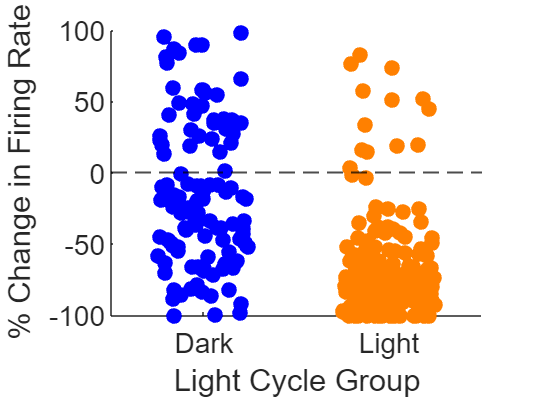

data = sixAves;  % Assuming you have a table `data` with columns: 'BLFR', 'FSFR', 'lightCycle'

% Calculate percentage change from BLFR to FSFR
data.PercentChange = ((data.FSFR - data.BLFR) ./ data.BLFR) * 100;

% Define colors for each lightCycle group
colors = containers.Map({'L', 'D'}, {[1, 0.5, 0], [0, 0, 1]});  % Orange for 'L', Blue for 'D'

% Convert lightCycle to a categorical variable and map to x-axis positions
lightCycleCell = cellstr(data.lightCycle);  % Convert character array to cell array
data.LightCycleX = double(categorical(lightCycleCell, {'D', 'L'}, 'Ordinal', true));  % Map 'D' to 1, 'L' to 2

% Add jitter to x-axis values
jitterAmount = 0.5;  % Adjust the jitter size as needed
jitteredX = data.LightCycleX + (rand(height(data), 1) - 0.5) * jitterAmount;

% Initialize figure
figure;
hold on;

% Iterate through the data to plot each unit
for i = 1:height(data)
    % Get the lightCycle and corresponding color
    lightCycle = char(data.lightCycle(i));  % Convert to string for lookup
    color = colors(lightCycle);  % Lookup the color for the group

    % Plot the point with jittered x-axis value
    scatter(jitteredX(i), data.PercentChange(i), 60, color, 'filled');
end

% Add a horizontal line at y=0 for reference
yline(0, '--k', 'LineWidth', 1);

% Set x-axis limits and labels
xlim([0.5, 2.5]);  % Extend slightly beyond the groups
xticks([1, 2]);  % Positions for 'D' and 'L'
xticklabels({'Dark', 'Light'});  % Labels for groups

% Set y-axis limits
ylim([-100, 100]);

% Add labels and title
xlabel('Light Cycle Group');
ylabel('% Change in Firing Rate');



% Set axis properties for better visibility
set(gca, 'FontName', 'Arial', 'FontSize', 14);

hold off;

Counting up how many units in each response group

% Initialize counts
increasedCount = struct('Light', 0, 'Dark', 0);
decreasedCount = struct('Light', 0, 'Dark', 0);

% Iterate through the data to calculate counts
for i = 1:height(data)
    lightCycle = char(data.lightCycle(i));  % Get the lightCycle group ('L' or 'D')
    percentChange = data.PercentChange(i);  % Get the percentage change

    % Determine if the unit increased or decreased and increment the appropriate count
    if percentChange > 0
        if lightCycle == 'L'
            increasedCount.Light = increasedCount.Light + 1;
        elseif lightCycle == 'D'
            increasedCount.Dark = increasedCount.Dark + 1;
        end
    elseif percentChange < 0
        if lightCycle == 'L'
            decreasedCount.Light = decreasedCount.Light + 1;
        elseif lightCycle == 'D'
            decreasedCount.Dark = decreasedCount.Dark + 1;
        end
    end
end

% Display the results
fprintf('Light Cycle: Light\n');

Light Cycle: Light


fprintf('Increased firing rate: %d units\n', increasedCount.Light);

Increased firing rate: 24 units


fprintf('Decreased firing rate: %d units\n\n', decreasedCount.Light);

Decreased firing rate: 165 units




fprintf('Light Cycle: Dark\n');

Light Cycle: Dark


fprintf('Increased firing rate: %d units\n', increasedCount.Dark);

Increased firing rate: 55 units


fprintf('Decreased firing rate: %d units\n', decreasedCount.Dark);

Decreased firing rate: 78 units


SingChan heat Map


% Extract unique units and spike times in seconds
units = table2array(rasterSpikes(:, 1));
unitlist = unique(units);
allspikes = table2array(rasterSpikes(:, 5));

% Extract lightCycle information and time in seconds
lightCycle = table2array(rasterSpikes(:, 3));
timeSeconds = table2array(rasterSpikes(:, 5));
timeMinutes = timeSeconds / 60;

% Determine lightCycle order (L units first, then D units)
lightCyclePerUnit = arrayfun(@(x) unique(lightCycle(units == x)), unitlist);
isL = strcmp(lightCyclePerUnit, 'L'); % Logical array for L units
isD = strcmp(lightCyclePerUnit, 'D'); % Logical array for D units

% Reorganize unitlist and spiketrain based on lightCycle
sortedUnitlist = [unitlist(isL); unitlist(isD)]; % L units first, then D units
spiketrain = arrayfun(@(x) allspikes(units == x), sortedUnitlist, 'UniformOutput', false);

% Define dynamic edges and bin interval
minTime = min(timeMinutes);
maxTime = max(timeMinutes);
dynamicEdges = minTime:5/60:maxTime;  % 5-second intervals in minutes
binInterval = dynamicEdges(2) - dynamicEdges(1);  % Calculate bin width in minutes
numBins = numel(dynamicEdges) - 1;  % Number of bins is one less than the number of edges

% Determine the bin indices for 15, 20, and 45 minutes
[~, bin15] = min(abs(dynamicEdges - 15));  % Closest bin to 15 minutes
[~, bin20] = min(abs(dynamicEdges - 20));  % Closest bin to 20 minutes
[~, bin45] = min(abs(dynamicEdges - 45));  % Closest bin to 45 minutes

% Create heatmap for sorted units
numUnits = numel(sortedUnitlist);
heatmap = zeros(numUnits, numBins);

for i = 1:numUnits
    heatmap(i, :) = histcounts(spiketrain{i} / 60, dynamicEdges); % Convert to minutes
end

% Normalize heatmap
heatmapNorm = heatmap ./ max(heatmap, [], 2);

% Plot heatmap
figure;
imagesc(heatmapNorm, [0 1]);
colormap('jet');
hold on;

% Add vertical lines for specific times
line([bin15, bin15], [1, numUnits], 'Color', 'w', 'LineWidth', 1.5);
line([bin20, bin20], [1, numUnits], 'Color', 'w', 'LineWidth', 1.5);
line([bin45, bin45], [1, numUnits], 'Color', 'w', 'LineWidth', 1.5);

% Define the maximum time to display (20 minutes)
maxDisplayTime = 20;  % Maximum time in minutes

% Define x-axis tick positions and labels for 0-20 minutes
xTicks = 0:5:maxDisplayTime; % Tick positions in minutes
xTickBinPositions = round((xTicks - minTime) / binInterval);
maxBinIndex = round((maxDisplayTime - minTime) / binInterval);

% Set axis limits and labels
set(gca, 'XLim', [0 maxBinIndex], ...
         'XTick', xTickBinPositions, ...
         'XTickLabel', xTicks, ...
         'YTick', 1:numUnits, ...
         'YTickLabel', sortedUnitlist, ...
         'YLim', [0 numUnits], ...
         'FontName', 'Arial', 'FontSize', 24);

xlabel('time (mins)');
%ylabel('unitID');
title('Binned Firing', 'FontName', 'Arial', 'FontSize', 24);



SixChan heat Map

sixNASpikes = all16AdjSpikes(~strcmp(all16AdjSpikes.lightCycle, 'X'), :);

# SixChan heat Map

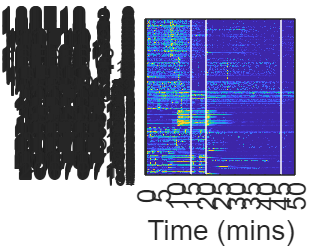

% Extract unique units and spike times in seconds
units = table2array(sixNASpikes(:, 1));
unitlist = unique(units);
allspikes = table2array(sixNASpikes(:, 5));

% Extract lightCycle information and time in seconds
lightCycle = table2array(sixNASpikes(:, 3));
timeSeconds = table2array(sixNASpikes(:, 5));
timeMinutes = timeSeconds / 60;

% Determine lightCycle order (L units first, then D units)
lightCyclePerUnit = arrayfun(@(x) unique(lightCycle(units == x)), unitlist);
isL = strcmp(lightCyclePerUnit, 'L'); % Logical array for L units
isD = strcmp(lightCyclePerUnit, 'D'); % Logical array for D units

% Reorganize unitlist and spiketrain based on lightCycle
sortedUnitlist = [unitlist(isL); unitlist(isD)]; % L units first, then D units
spiketrain = arrayfun(@(x) allspikes(units == x), sortedUnitlist, 'UniformOutput', false);

% Define dynamic edges and bin interval
minTime = min(timeMinutes);
maxTime = max(timeMinutes);
dynamicEdges = minTime:5/60:maxTime;  % 5-second intervals in minutes
binInterval = dynamicEdges(2) - dynamicEdges(1);  % Calculate bin width in minutes
numBins = numel(dynamicEdges) - 1;  % Number of bins is one less than the number of edges

% Determine the bin indices for 15, 20, and 45 minutes
[~, bin15] = min(abs(dynamicEdges - 15));  % Closest bin to 15 minutes
[~, bin20] = min(abs(dynamicEdges - 20));  % Closest bin to 20 minutes
[~, bin45] = min(abs(dynamicEdges - 45));  % Closest bin to 45 minutes

% Create heatmap for sorted units
numUnits = numel(sortedUnitlist);
heatmap = zeros(numUnits, numBins);

for i = 1:numUnits
    heatmap(i, :) = histcounts(spiketrain{i} / 60, dynamicEdges); % Convert to minutes
end

% Normalize heatmap
heatmapNorm = heatmap ./ max(heatmap, [], 2);

% Plot heatmap
figure;
imagesc(heatmapNorm, [0 1]);
colormap('parula');
hold on;

% Add vertical lines for specific times
line([bin15, bin15], [1, numUnits], 'Color', 'w', 'LineWidth', 1.5);
line([bin20, bin20], [1, numUnits], 'Color', 'w', 'LineWidth', 1.5);
line([bin45, bin45], [1, numUnits], 'Color', 'w', 'LineWidth', 1.5);

% Define the maximum time to display (20 minutes)
maxDisplayTime = 50;  % Maximum time in minutes

% Define x-axis tick positions and labels for 0-20 minutes
xTicks = 0:5:maxDisplayTime; % Tick positions in minutes
xTickBinPositions = round((xTicks - minTime) / binInterval);
maxBinIndex = round((maxDisplayTime - minTime) / binInterval);

% Set axis limits and labels
set(gca, 'XLim', [0 maxBinIndex], ...
         'XTick', xTickBinPositions, ...
         'XTickLabel', xTicks, ...
         'YTick', 1:numUnits, ...
         'YTickLabel', sortedUnitlist, ...
         'YLim', [0 numUnits], ...
         'FontName', 'Arial', 'FontSize', 24);

xlabel('Time (mins)');

%ylabel('unitID');
%title('Binned Firing', 'FontName', 'Arial', 'FontSize', 24);



# Average Firing over time line graph

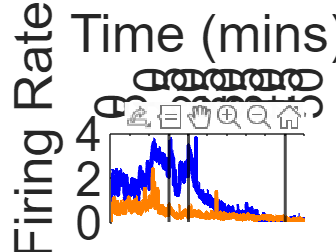

binSize = 1;
% Extract unique lighCycle groups and unitIDs
lightCycles = unique(sixNASpikes.lightCycle);
unitIDs = unique(sixNASpikes.unitID);

% Define the time bins
minTime = min(sixNASpikes.adjustedTimestamp);
maxTime = max(sixNASpikes.adjustedTimestamp);
edges = minTime:binSize:maxTime;

% Initialize data structure for firing rates
firingRatesByUnit = zeros(length(edges)-1, length(unitIDs), length(lightCycles));
timeBins = (edges(1:end-1) + binSize/2) / 60; % Convert bin centers to minutes

% Define custom colors for lightCycle groups
groupColors = containers.Map({'L', 'D', 'X'}, {[1, 0.5, 0], [0, 0, 1], [1, 0, 0]}); % 'L' = orange, 'D' = blue, 'X' = red



% Loop through each lightCycle group
for g = 1:length(lightCycles)
    % Filter spikes for the current lightCycle group
    groupSpikes = sixNASpikes(sixNASpikes.lightCycle==lightCycles(g), :);

    % Loop through each unit
    for u = 1:length(unitIDs)
        % Filter spikes for the current unit
        unitSpikes = groupSpikes(groupSpikes.unitID==unitIDs(u), :);

        % Calculate histogram (spikes per bin)
        counts = histcounts(unitSpikes.adjustedTimestamp, edges);

        % Normalize firing rate (spikes per second)
        firingRatesByUnit(:, u, g) = counts / binSize;
    end
end

% Average firing rate across units for each lightCycle group
meanFiringRates = mean(firingRatesByUnit, 2, 'omitnan');
meanFiringRates = squeeze(meanFiringRates); % Remove singleton dimensions

% Plot the data
figure;
hold on;
for g = 1:length(lightCycles)
    % Get the color for the current group
    currentColor = groupColors(char(lightCycles(g)));

    % Plot the line
    plot(timeBins, meanFiringRates(:, g), 'LineWidth', 2, 'Color', currentColor, ...
        'DisplayName', char(lightCycles(g)));
end

% Add black vertical lines at 15, 20, and 40 minutes
xline(15, 'k', 'LineWidth', 1.5);
xline(20, 'k', 'LineWidth', 1.5);
xline(45, 'k', 'LineWidth', 1.5);

hold off;

% Add labels, legend, and title
xlabel('Time (mins)');
ylabel('Average Firing Rate (Hz)');

set(gca, 'FontSize', 12, 'FontName', 'Arial', 'FontSize', 24); % Adjust font size
set(gca, 'XAxisLocation', 'top'); % Move x-axis to the top of the graph

% Adjust x-axis limits and ticks
xlim([0, 50]);
xticks(0:5:50);